% This MATLAB script was created to fulfill the thesis requirements of Keith Sequeira (Msc Computational Fluid Dynamics, IRP: 2023-24),, titled "Computational Evaluation of RANS Models in Predicting Jet Blast Effects."
% This MATLAB code was made with assistance from ChatGPT, Bing AI and Perplexity

% ASCII Inputs
filename_id = {'', '', ''};
filenames_ba = {'', '', ''};
filenames_to = {'', '', ''};


velocity_threshold = 15.64;

% Create a figure for the plots
figure;

% Define colors and markers for each dataset
colors = [0 0 1; 0 1 0; 1 0 0]; % Blue, Green, Red
markers = {'o', 's', '^'}; % Circle, Square, Triangle

% Define BPR values for each dataset
bpr_values_id = [3, 9, 15];
bpr_values_ba = [3, 9, 15];
bpr_values_to = [3, 9, 15];

% Initialize arrays to store plot handles and labels
all_handles = [];
all_labels = {};

% Plot for filename_id
subplot(3, 1, 1); % Create a subplot for filename_id
hold on;
text(-0.1, 1.05, 'a)', 'Units', 'normalized', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'right');
plotHandles_id = gobjects(1, length(filename_id));

for i = 1:length(filename_id)
    data = load(filename_id{i});
    x_coords = data(:, 2) - 30;
    z_coords = data(:, 4);
    velocity = data(:, 5);
    
    scatter(x_coords, z_coords, 10, 'w', 'filled', 'MarkerFaceAlpha', 0.05);
    high_velocity_indices = velocity > velocity_threshold;
    plotHandles_id(i) = scatter(x_coords(high_velocity_indices), z_coords(high_velocity_indices), 50, colors(i,:), 'filled', 'MarkerFaceAlpha', 0.9, 'Marker', markers{i});
end

xlabel('X/D');
ylabel('Z/D');
xlim([0 500]);
ylim([-40 40]);
grid on;
hold off;

% Plot for filenames_ba
subplot(3, 1, 2); % Create a subplot for filenames_ba
hold on;
text(-0.1, 1.05, 'b)', 'Units', 'normalized', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'right');
plotHandles_ba = gobjects(1, length(filenames_ba));

for i = 1:length(filenames_ba)
    data = load(filenames_ba{i});
    x_coords = data(:, 2) - 30;
    z_coords = data(:, 4);
    velocity = data(:, 5);
    
    scatter(x_coords, z_coords, 10, 'w', 'filled', 'MarkerFaceAlpha', 0.05);
    high_velocity_indices = velocity > velocity_threshold;
    plotHandles_ba(i) = scatter(x_coords(high_velocity_indices), z_coords(high_velocity_indices), 50, colors(i,:), 'filled', 'MarkerFaceAlpha', 0.9, 'Marker', markers{i});
end

xlabel('X/D');
ylabel('Z/D');
xlim([0 500]);
ylim([-40 40]);
grid on;
hold off;

% Plot for filenames_to
subplot(3, 1, 3); % Create a subplot for filenames_to
hold on;
text(-0.1, 1.05, 'c)', 'Units', 'normalized', 'FontWeight', 'bold', 'FontSize', 12, 'HorizontalAlignment', 'right');
plotHandles_to = gobjects(1, length(filenames_to));

for i = 1:length(filenames_to)
    data = load(filenames_to{i});
    x_coords = data(:, 2) - 30;
    z_coords = data(:, 4);
    velocity = data(:, 5);
    
    scatter(x_coords, z_coords, 10, 'w', 'filled', 'MarkerFaceAlpha', 0.05);
    high_velocity_indices = velocity > velocity_threshold;
    plotHandles_to(i) = scatter(x_coords(high_velocity_indices), z_coords(high_velocity_indices), 50, colors(i,:), 'filled', 'MarkerFaceAlpha', 0.9, 'Marker', markers{i});
end

xlabel('X/D');
ylabel('Z/D');
xlim([0 500]);
ylim([-40 40]);
grid on;
hold off;

% Adjust subplot positions to make space for the legend
subplot_positions = get(gcf, 'Position'); % Get current figure position
subplot_positions(4) = subplot_positions(4) - 0.1; % Reduce the height of the figure
set(gcf, 'Position', subplot_positions);

% Collect plot handles and labels for legend
% Use only BPR labels for the legend
all_handles = [plotHandles_id, plotHandles_ba, plotHandles_to];
unique_bpr_values = unique([bpr_values_id, bpr_values_ba, bpr_values_to]);
all_labels = arrayfun(@(bpr) sprintf('BPR %d', bpr), unique_bpr_values, 'UniformOutput', false);

% Create a legend in the bottom subplot
subplot(3, 1, 3); % Ensure the legend is in the bottom subplot
% Create legend with adjusted position
lgd = legend(all_handles, all_labels, 'Location', 'southoutside', 'Orientation', 'horizontal', 'NumColumns', 3, 'FontSize', 8);

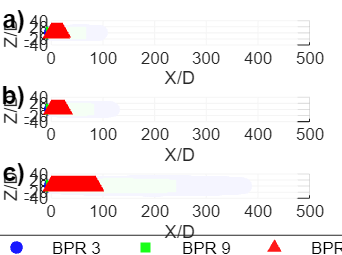


% Adjust the position of the legend to be outside the subplot
lgd.Position(2) = lgd.Position(2) - 0.7; % Move legend down by 10% of figure height

% Save the figure with an appropriate filename
saveas(gcf, 'Kosst_Figure.png'); % Adjust the filename as needed